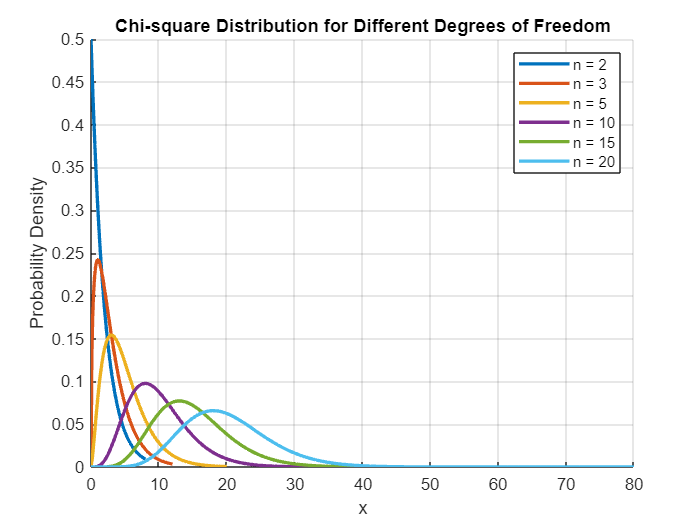

array_n = [2, 3, 5, 10, 15, 20];

figure;
hold on;

for n = array_n
    [Densite, Intervalle] = Chi2(n);
    plot(Intervalle, Densite, 'LineWidth', 2, 'DisplayName', ['n = ', num2str(n)]);
end

hold off;

title('Chi-square Distribution for Different Degrees of Freedom');
xlabel('x');
ylabel('Probability Density');
legend('show');
grid on;

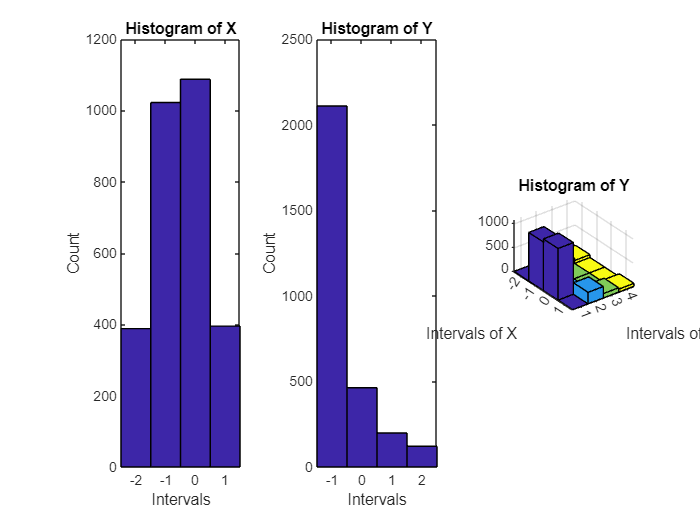

NbTirages = 3000;
[X, Z] = GenereXZ(NbTirages);

[HistoX, HistoZ, HistoXZ] = CalculHistogrammeXZ(X, Z);

x = [-2, -1, 0, 1, 2];
z = [-1, 0, 1, 2, 3];

figure;
subplot(1, 3, 1);
bar(x(1:end-1), HistoX, 'hist');
title('Histogram of X');
xlabel('Intervals');
ylabel('Count');
subplot(1, 3, 2);
bar(z(1:end-1), HistoZ, 'hist');
title('Histogram of Y');
xlabel('Intervals');
ylabel('Count');
subplot(1, 3, 3);
bar3(x(1:end-1), HistoXZ, 'hist');
title('Histogram of Y');
xlabel('Intervals of Y');
ylabel('Intervals of X');

CoefficientConfiance = 0.99;
Independance = IndependanceChi2(HistoX, HistoZ, HistoXZ, CoefficientConfiance)

TestStat = 2.8995e+03

threshold = 30.5779

Independance = logical
   0


X = randn(1, NbTirages);
Z = randn(1, NbTirages);

numBins = 4;

HistoX = histcounts(X, numBins);
HistoZ = histcounts(Z, numBins);
HistoXZ = histcounts2(X, Z, numBins);

CoefficientConfiance = 0.99;
Independance = IndependanceChi2(HistoX, HistoZ, HistoXZ, CoefficientConfiance)

TestStat = 5.0099

threshold = 30.5779

Independance = logical
   1


NbTirages = 3000;
N = 5;

Z = GenereZ(NbTirages, N);
CoefficientConfiance = 0.99;
Adaptation = TestDistributionChi2(Z, N, CoefficientConfiance)

TestStat = 24.6618

threshold = 21.6660

Adaptation = logical
   0


Adaptation = TestKolmogorov(Z, N, CoefficientConfiance)

TestStat = 0.0752

threshold = 0.0310

Adaptation = logical
   0


NbEch = 100;
[Inside, BorneInf, BorneSup] = VerifIntervalle(NbEch)

Inside = logical
   1


BorneInf = -0.2759

BorneSup = 0.0530

NbTests = 10000;
Proba1 = EstimeProba(NbEch, NbTests)

Proba1 = 0.8970

Proba2 = EstimeProbaTchebychev(NbEch, NbTests)

Proba2 = 1

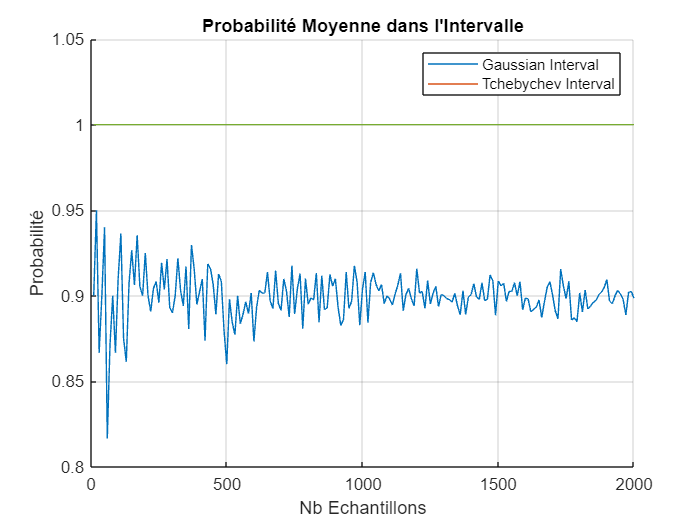

array_NbEch = 10:10:2000;
array_proba1 = zeros(length(array_NbEch));
array_proba2 = zeros(length(array_NbEch));

for i = 1:length(array_NbEch)

    array_proba1(i) = EstimeProba(NbEch, array_NbEch(i));
    array_proba2(i) = EstimeProbaTchebychev(NbEch, array_NbEch(i));
end

figure;
hold on;
plot(array_NbEch, array_proba1);
plot(array_NbEch, array_proba2);
hold off;
title("Probabilité Moyenne dans l'Intervalle");
xlabel('Nb Echantillons');
ylim([0.8, 1.05])
ylabel('Probabilité');
legend('Gaussian Interval', 'Tchebychev Interval');
grid on;